# Figure S2F

### Load Data

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);

dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A082_data.mat'],'S','settings','allIF');
conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;

   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcGate = false(length(dat.POI(:,1)),1);
    dbf4Gate = false(length(dat.POI(:,1)),1);
    dbf4level = NaN*ones(length(dat.POI(:,1)),1);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 5 & dat.POI(n,1) + 7 < numFrames
            apcGate(n) = dat.apcAreaNorm(n,dat.POI(n,1) - 5) > .4 & ...
                dat.apcAreaNorm(n,dat.POI(n,1) +7) < .1 ;
        end

         if dat.POI(n,1) > 2 * framesPerHr & dat.POI(n,1) < numFrames - 2 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .2 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 2* framesPerHr] )) < .01;
        end

        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            dbf4Gate(n) = nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .8 & ...
              nanmean(dat.sigNorm(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] ))< 1;
  
        end

    end
    S(i).apcGate = apcGate;
   S(i).dbf4Gate = dbf4Gate;
    S(i).dbf4level = dbf4level;
     S(i).apcExpressGate = apcExpressGate;
end

**Plot traces aligne****d**

ans = 1170

ans = 257

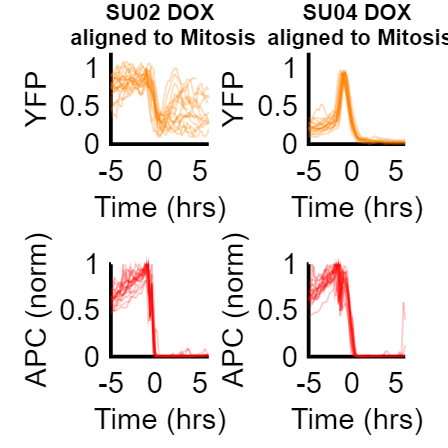

conds=[1 3];
%SU02 = DBF4
%SU04 = Geminin

poiAlign = [ 1 ];
rng(26)
alignNames = {'Mitosis','APC '};
xlimits = {[-5 6],[-10,10],[-5 12]};
for p = 1:length(poiAlign)
    figure('pos',[10 10 length(conds)*300 600 ]),
    for i=1:length(conds)
       inds = ~isnan(S(conds(i)).POI(:,poiAlign(p)))&...
           S(conds(i)).dbf4Gate  &...
           S(conds(i)).POI_realtime(:,1) >5 &...
       S(conds(i)).apcExpressGate;
        cells = find(inds);
        length(cells)
        for numcell = randsample(cells,min([20 length(cells)]))'
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
            subplot(2,length(conds),i),hold on
           patchline(timeAligned,nansmooth(S(conds(i)).sigNorm(numcell,:),3),...
               'edgecolor',[1 0.5 0],'linewidth',1,'edgealpha',0.25);
            title({conditions{conds(i),1}, [' aligned to ' alignNames{(p)}]},'FontSize',12);
            ylabel('YFP');
            ylim([0 1.2]);
            xlim(xlimits{p});
            xlabel('Time (hrs)');
            subplot(2,length(conds),i+length(conds)),hold on
            patchline(timeAligned,S(conds(i)).apcNormM(numcell,:),...
                'edgecolor','r','linewidth',1,'edgealpha',0.2);
            
            ylabel('APC (norm)');
            xlabel('Time (hrs)');
           ylim([0 1]); 
            xlim(xlimits{p});
         
        end
    end
end

% print_pdf(['fig_S2F.pdf'])